clc;
clear;
close all;

%% Carga del modelo
load('modelo_lin.mat')

modelo = latmod;

Alat = modelo.A;
Blat = modelo.B;
Clat = modelo.C

Clat =     0.0588         0         0         0         0
         0    1.0000         0         0         0
         0         0    1.0000         0         0
         0         0         0    1.0000         0
         0         0         0         0    1.0000


Dlat = modelo.D

Dlat =      0     0
     0     0
     0     0
     0     0
     0     0



%% Eliminacion de datos irrelevantes
Alat(abs(Alat)<1e-10)=0;
Blat(abs(Blat)<1e-10)=0;
Clat(abs(Clat)<1e-10)=0;
Dlat(abs(Dlat)<1e-10)=0;

%% Seleccion de estados
modelo;
Clat=Clat(4:5,:);
Dlat=Dlat(4:5,:);
G=ss(Alat,Blat,Clat,Dlat)

G =
 
  A = 
            x1       x2       x3       x4       x5
   x1   -0.875   0.8751   -16.82    9.791        0
   x2   -2.831   -16.14    3.377        0        0
   x3    1.706   0.5154   -2.783        0        0
   x4        0        1  0.05385        0        0
   x5        0        0    1.001        0        0
 
  B = 
           u1      u2
   x1       0   5.317
   x2  -156.9  -5.022
   x3   11.54  -82.27
   x4       0       0
   x5       0       0
 
  C = 
       x1  x2  x3  x4  x5
   y1   0   0   0   1   0
   y2   0   0   0   0   1
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Continuous-time state-space model.




%% Filtros
s=tf('s');

wB1=8*2*pi;
A1=0.0003;
A12=0.00003;
M1=0.3;

wB3=6*2*pi;
A3=0.1;
M3=1;

% W1=(0.5*s+0.015)/(s+0.00015);
W1=[(s/M1+wB1)/(s+wB1*A1) 0;
    0 (s/M1+wB1)/(s+wB1*A12)];
W2=[tf(1,1) 0;
    0 tf(1,1)];
W3=[(1+s/M3)/(1+(s/wB3)) 0;
    0 (1+s/M3)/(1+(s/wB3))];

%% Grafica de filtros
% hold on
% bodemag(1/W1,'r');
% bodemag(1/W2,'g');
% bodemag(1/W3,'b');
% hold off

%% Calculo del controlador
[K,CL,gamma]=mixsyn(G,W1,W2,W3)

K =
 
  A = 
               x1          x2          x3          x4          x5          x6          x7          x8          x9
   x1    -0.01508   1.466e-16  -2.661e-18  -6.335e-17  -1.753e-20  -9.535e-20  -2.073e-18  -6.514e-18  -1.226e-16
   x2   2.991e-11   -0.001508  -1.132e-11  -2.122e-10  -5.822e-14  -3.524e-13  -6.948e-12  -2.511e-11  -4.108e-10
   x3   5.744e-11   9.384e-10       -37.7  -4.056e-10  -1.113e-13  -6.757e-13  -1.328e-11          32  -7.853e-10
   x4   0.0001576    0.002585  -5.966e-05       -37.7  -3.066e-07  -1.857e-06  -3.659e-05  -0.0001323          32
   x5      -194.1       -2772       69.61        1124     -0.4531       3.367       26.01       177.2        2382
   x6   1.413e+04       -1667       -4927       606.6       1.766      -192.2       10.83  -1.283e+04        1473
   x7        1978   4.321e+04      -719.6  -1.752e+04       -5.19      -25.28      -669.1       -1658  -3.714e+04
   x8   6.766e-11   1.105e-09  -2.565e-11  -4.777e-10  -1.311e-13          

gamma = 7.6260




%% Conexion de planta
OL=series(K,G)

OL =
 
  A = 
                x1          x2          x3          x4          x5          x6          x7          x8          x9         x10
   x1       -0.875      0.8751      -16.82       9.791           0      -194.1       -2772       69.61        1124      0.4219
   x2       -2.831      -16.14       3.377           0           0   1.413e+04       -1667       -4927       606.6       4.597
   x3        1.706      0.5154      -2.783           0           0        1978   4.321e+04      -719.6  -1.752e+04      -6.896
   x4            0           1     0.05385           0           0           0           0           0           0           0
   x5            0           0       1.001           0           0           0           0           0           0           0
   x6            0           0           0           0           0    -0.01508   1.466e-16  -2.661e-18  -6.335e-17  -1.753e-20
   x7            0           0           0           0           0   2.991e-11   -0.001508  -1.13

% 
I = eye(2)

I =      1     0
     0     1


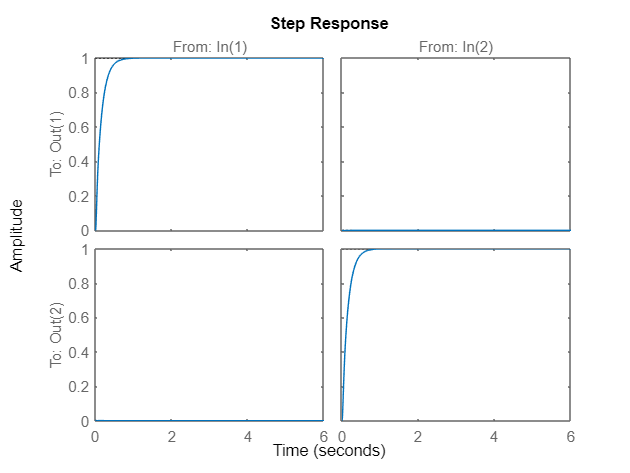

% 
GCL=feedback(OL,I);

figure (1)
step(GCL)

% 

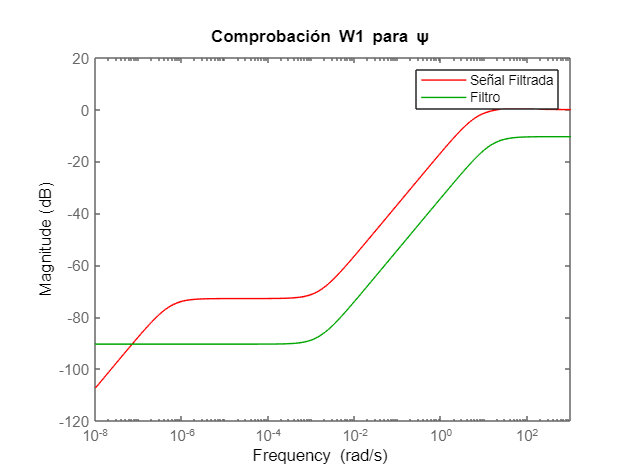

% % step(CL), xlim([0 10])
%% Comprobación W1
S = feedback(1,OL(2,2));
figure (2)
bodemag(S,'r');
hold on
bodemag(1/W1(2,2),'g'), title("Comprobación W1 para \psi");
legend("Señal Filtrada", "Filtro");
hold off

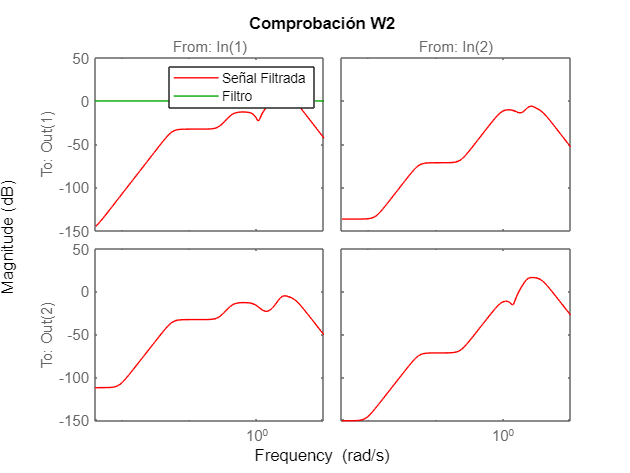


%Comprobación W2
S = feedback(1,OL(2,2));
figure(3)
bodemag(S*K,'r');
hold on
bodemag(1/W2(2,2),'g'), title("Comprobación W2");
legend("Señal Filtrada", "Filtro");
hold off

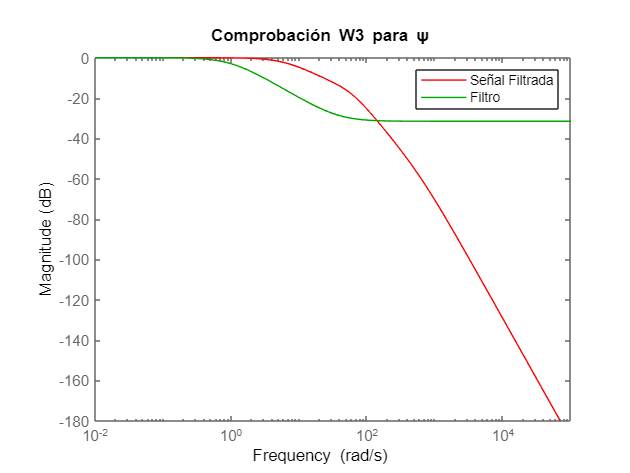


%% Comprobacion W3

T = feedback(OL(2,2),1);
figure (4)
bodemag(T,'r');
hold on
bodemag(1/W3(2,2),'g'), title("Comprobación W3 para \psi");
legend("Señal Filtrada", "Filtro");
hold off

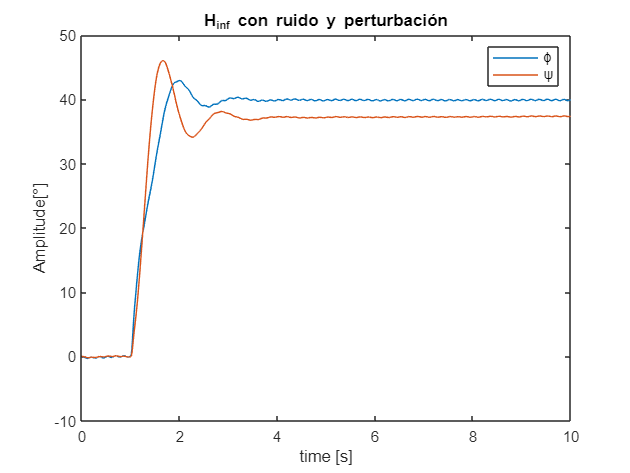

figure()
plot(out.ScopeData1.time,out.ScopeData1.signals.values)
title('H_{inf} con ruido y perturbación')
legend({'\phi','\psi'})
xlabel('time [s]') 
ylabel('Amplitude[°]') 